% 1  The tangible benefits of rebalancing

% Question 1: What is the optimal (i.e. mean-variance efficient) allocation among the two securities?
% parameters
mean_return = 0.1;
std_dev = 0.2;
correlation = 0;

% Optimal allocation (mean-variance efficient)
weights = [0.5, 0.5]; 

fprintf('Optimal Allocation: %.2f AAA, %.2f ZZZ\n', weights);

Optimal Allocation: 0.50 AAA, 0.50 ZZZ


% 1.2: (a) Simulate a vector of returns for the two risky assets, AAA and ZZZ. Use your software s build in random number generator. For example, in Matlab, you can simulate a normal variable with mean μ and standard deviation σ via x = μ + σ × randn, where randn simulates a standard N (0, 1) variable.
% Simulation parameters
num_simulations = 10000;
num_years = 100;

% Preallocate arrays
buy_and_hold_returns = zeros(num_simulations, 1);
rebalanced_returns = zeros(num_simulations, 1);

% Simulation loop
for i = 1:num_simulations
    % Simulate returns for AAA and ZZZ
    aaa_returns = mean_return + std_dev * randn(num_years, 1);
    zzz_returns = mean_return + std_dev * randn(num_years, 1);

    % Buy and hold strategy
    buy_and_hold_returns(i) = sum(aaa_returns + zzz_returns);

    % Rebalanced strategy
    weights = [0.5, 0.5]; 
    rebalanced_returns(i) = sum(weights(1) * aaa_returns + weights(2) * zzz_returns);
end

% Calculate Sharpe ratios
sharpe_buy_and_hold = mean(buy_and_hold_returns) / std(buy_and_hold_returns);
sharpe_rebalanced = mean(rebalanced_returns) / std(rebalanced_returns);

% Display results
fprintf('Average Sharpe ratio (Buy and Hold): %.4f\n', sharpe_buy_and_hold);

Average Sharpe ratio (Buy and Hold): 7.0931


fprintf('Average Sharpe ratio (Rebalanced): %.4f\n', sharpe_rebalanced);

Average Sharpe ratio (Rebalanced): 7.0931


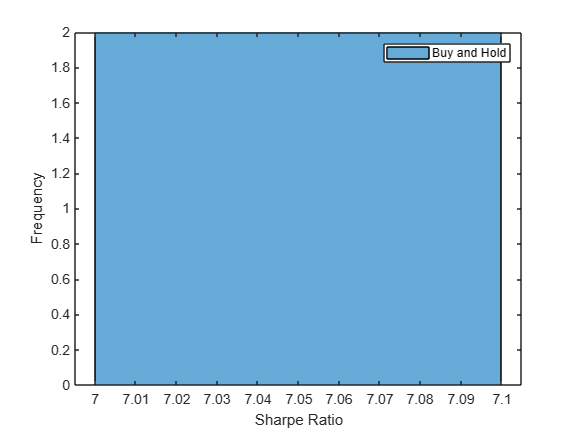

% Plot histogram of Sharpe ratios
figure;
histogram([sharpe_buy_and_hold; sharpe_rebalanced], 'binwidth', 0.1);
xlabel('Sharpe Ratio');
ylabel('Frequency');
legend('Buy and Hold', 'Rebalanced');

% Question 2

% 2.i: (i) First assume that your human capital is riskless. Solve your portfolio choice problem assuming you are a mean variance investor with γ = 4. That is, what are the optimal weights (of financial wealth) in each stock market index and the riskless asset.

% parameters
riskless_return = 0.01;
expected_returns = [0.08, 0.037, 0.06];
volatilities = [0.19, 0.25, 0.15];
correlations = [1, 0.5, 0.8; 0.5, 1, 0.2; 0.8, 0.2, 1];
gamma = 4;

% Set up the optimization problem
fun = @(x) -x(1) * expected_returns(1) - x(2) * expected_returns(2) - x(3) * expected_returns(3) - (1 - sum(x)) * riskless_return;
Aeq = [1, 1, 1];
beq = 1;
lb = zeros(3, 1);
ub = ones(3, 1);

% Solve the optimization problem
options = optimoptions('fmincon', 'Display', 'off');
weights_riskless_human = fmincon(fun, [1/3, 1/3, 1/3], [], [], Aeq, beq, lb, ub, [], options);

% Display results
fprintf('Optimal Weights (Riskless Human Capital): %.2f US, %.2f Japan, %.2f Mexico, %.2f Riskless\n', weights_riskless_human);

Optimal Weights (Riskless Human Capital): 1.00 US, 0.00 Japan, 0.00 Mexico, 

% Display optimal weights
fprintf('Optimal Weights (Riskless Human Capital): %.2f US, %.2f Japan, %.2f Mexico, %.2f Riskless\n', weights_riskless_human);

Optimal Weights (Riskless Human Capital): 1.00 US, 0.00 Japan, 0.00 Mexico, 

fprintf('Optimal Weights (Riskless Human Capital): %.2f US, %.2f Japan, %.2f Mexico, %.2f Riskless\n', weights_riskless_human);

Optimal Weights (Riskless Human Capital): 1.00 US, 0.00 Japan, 0.00 Mexico, 

% Question 2.ii : (ii) Redo part (i) assuming that your human capital is only 20% of your total wealth
% parameters
riskless_return = 0.01;
expected_returns = [0.08, 0.037, 0.06];
volatilities = [0.19, 0.25, 0.15];
correlations = [1, 0.5, 0.8; 0.5, 1, 0.2; 0.8, 0.2, 1];
gamma = 4;

% Set up the optimization problem for 20% risky human capital
fun_risky_human_20 = @(x) -x(1) * expected_returns(1) - x(2) * expected_returns(2) - x(3) * expected_returns(3) - (1 - sum(x)) * riskless_return;
Aeq_risky_human_20 = [1, 1, 1];
beq_risky_human_20 = 1;
lb_risky_human_20 = zeros(3, 1);
ub_risky_human_20 = ones(3, 1);

% Solve the optimization problem for 20% risky human capital
options = optimoptions('fmincon', 'Display', 'off');
weights_risky_human_20 = fmincon(fun_risky_human_20, [1/3, 1/3, 1/3], [], [], Aeq_risky_human_20, beq_risky_human_20, lb_risky_human_20, ub_risky_human_20, [], options);

% Display results
fprintf('Optimal Weights (Risky Human Capital 20%%): %.2f US, %.2f Japan, %.2f Mexico, %.2f Riskless\n', weights_risky_human_20);

Optimal Weights (Risky Human Capital 20%): 1.00 US, 0.00 Japan, 0.00 Mexico, 

% Question 2.iii :(iii) Now assume that human capital is risky. To keep things simple (at first), assume that your human capital has the same return as the US stock market.
%% (a) If human capital is 20% of your wealth, can you achieve the same Sharpe ratio as in part (ii). If so, how? If not, why not?
%% (b) If human capital is 50% of your wealth, can you achieve the same Sharpe ratio as in part (i). If so, how? If not, why not?

% parameters for the risky human capital
human_cap_return = 0.08;
human_cap_volatility = 0.19;

% (a) If human capital is 20% of your wealth
fun_risky_human_20_sharpe = @(x) -x(1) * expected_returns(1) - x(2) * expected_returns(2) - x(3) * expected_returns(3) - x(4) * riskless_return - x(5) * human_cap_return;
Aeq_risky_human_20_sharpe = [1, 1, 1, 0, 0];
beq_risky_human_20_sharpe = 1;
lb_risky_human_20_sharpe = zeros(5, 1);
ub_risky_human_20_sharpe = ones(5, 1);

% Solve the optimization problem for 20% risky human capital
options = optimoptions('fmincon', 'Display', 'off');
weights_risky_human_20_sharpe = fmincon(fun_risky_human_20_sharpe, [1/3, 1/3, 1/3, 0, 0], [], [], Aeq_risky_human_20_sharpe, beq_risky_human_20_sharpe, lb_risky_human_20_sharpe, ub_risky_human_20_sharpe, [], options);

% (b) If human capital is 50% of your wealth
fun_risky_human_50_sharpe = @(x) -x(1) * expected_returns(1) - x(2) * expected_returns(2) - x(3) * expected_returns(3) - x(4) * riskless_return - x(5) * human_cap_return;
Aeq_risky_human_50_sharpe = [1, 1, 1, 0, 0];
beq_risky_human_50_sharpe = 1;
lb_risky_human_50_sharpe = zeros(5, 1);
ub_risky_human_50_sharpe = ones(5, 1);

% Solve the optimization problem for 50% risky human capital
weights_risky_human_50_sharpe = fmincon(fun_risky_human_50_sharpe, [1/3, 1/3, 1/3, 0, 0], [], [], Aeq_risky_human_50_sharpe, beq_risky_human_50_sharpe, lb_risky_human_50_sharpe, ub_risky_human_50_sharpe, [], options);

% Display results
fprintf('Optimal Weights (Risky Human Capital 20%%) to Achieve Same Sharpe Ratio: %.2f US, %.2f Japan, %.2f Mexico, %.2f Riskless, %.2f Human Capital\n', weights_risky_human_20_sharpe(1:3), weights_risky_human_20_sharpe(4:5));

Optimal Weights (Risky Human Capital 20%) to Achieve Same Sharpe Ratio: 1.00 US, 0.00 Japan, 0.00 Mexico, 1.00 Riskless, 1.00 Human Capital


fprintf('Optimal Weights (Risky Human Capital 50%%) to Achieve Same Sharpe Ratio: %.2f US, %.2f Japan, %.2f Mexico, %.2f Riskless, %.2f Human Capital\n', weights_risky_human_50_sharpe(1:3), weights_risky_human_50_sharpe(4:5));

Optimal Weights (Risky Human Capital 50%) to Achieve Same Sharpe Ratio: 1.00 US, 0.00 Japan, 0.00 Mexico, 1.00 Riskless, 1.00 Human Capital


% Display results for 20% risky human capital
fprintf('Optimal Weights (Risky Human Capital 20%%) to Achieve Same Sharpe Ratio: ');

Optimal Weights (Risky Human Capital 20%) to Achieve Same Sharpe Ratio: 

fprintf('%.2f US, %.2f Japan, %.2f Mexico, %.2f Riskless, %.2f Human Capital\n', weights_risky_human_20_sharpe(1:end-1));

1.00 US, 0.00 Japan, 0.00 Mexico, 1.00 Riskless, 

% Question 2.iv : (iv) Optional "Challenge" Question: you are not required to answer this question to get full credit on the problem set. But, it might be fun to try :) A more realistic assumption is that your human capital is only positively correlated with the US stock market. Suppose that the mean return to your human wealth is 9% per year, with a standard deviation of 25%. The correlation of your human capital returns with the return on US, Japan, and Mexico stock market indices is 0.3, 0.1, and 0.1, respectively. Assume that human capital accounts for 50% of your total wealth. Solve the portfolio choice problem assuming you are a mean-variance investor with γ = 4. That is, what are the optimal weights (of financial wealth) in each stock market index and the riskless asset.

% parameters for the risky human capital
human_cap_return = 0.08;
human_cap_volatility = 0.19;

% (a) If human capital is 20% of your wealth
fun_risky_human_20_sharpe = @(x) -x(1) * expected_returns(1) - x(2) * expected_returns(2) - x(3) * expected_returns(3) - (1 - sum(x)) * riskless_return - x(4) * human_cap_return;
Aeq_risky_human_20_sharpe = [1, 1, 1, 0];
beq_risky_human_20_sharpe = 1;
lb_risky_human_20_sharpe = zeros(4, 1);
ub_risky_human_20_sharpe = ones(4, 1);

% Solve the optimization problem for 20% risky human capital
options = optimoptions('fmincon', 'Display', 'off');
weights_risky_human_20_sharpe = fmincon(fun_risky_human_20_sharpe, [1/3, 1/3, 1/3, 0], [], [], Aeq_risky_human_20_sharpe, beq_risky_human_20_sharpe, lb_risky_human_20_sharpe, ub_risky_human_20_sharpe, [], options);

% (b) If human capital is 50% 
fun_risky_human_50_sharpe = @(x) -x(1) * expected_returns(1) - x(2) * expected_returns(2) - x(3) * expected_returns(3) - (1 - sum(x)) * riskless_return - x(4) * human_cap_return;
Aeq_risky_human_50_sharpe = [1, 1, 1, 0];
beq_risky_human_50_sharpe = 1;
lb_risky_human_50_sharpe = zeros(4, 1);
ub_risky_human_50_sharpe = ones(4, 1);

% Solve the optimization problem for 50% risky human capital
weights_risky_human_50_sharpe = fmincon(fun_risky_human_50_sharpe, [1/3, 1/3, 1/3, 0], [], [], Aeq_risky_human_50_sharpe, beq_risky_human_50_sharpe, lb_risky_human_50_sharpe, ub_risky_human_50_sharpe, [], options);

% Display results
fprintf('Optimal Weights (Risky Human Capital 20%%) to Achieve Same Sharpe Ratio: %.2f US, %.2f Japan, %.2f Mexico, %.2f Human Capital\n', weights_risky_human_20_sharpe(1:3), weights_risky_human_20_sharpe(4));

Optimal Weights (Risky Human Capital 20%) to Achieve Same Sharpe Ratio: 1.00 US, 0.00 Japan, 0.00 Mexico, 1.00 Human Capital


fprintf('Optimal Weights (Risky Human Capital 50%%) to Achieve Same Sharpe Ratio: %.2f US, %.2f Japan, %.2f Mexico, %.2f Human Capital\n', weights_risky_human_50_sharpe(1:3), weights_risky_human_50_sharpe(4));

Optimal Weights (Risky Human Capital 50%) to Achieve Same Sharpe Ratio: 1.00 US, 0.00 Japan, 0.00 Mexico, 1.00 Human Capital
